## CODIFICAÇÃO CONVOLUCIONAL [133, 171], n = 1, k = 2, q = 7.

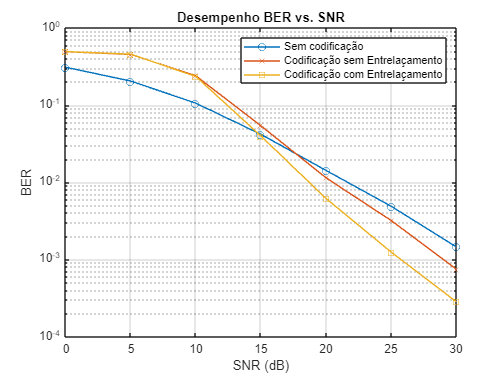

clc; close all; clear;

% Parametros da simulação
M = 16; % ordem da modulação QAM
k_QAM = log2(M); % numero de bits por simbolo
SNR_dB = 0:5:30;
n_transmissoes = 1e4;
n_bits_transmissao = 64;

%treliça
t = poly2trellis(7, [133, 171]); %criação da treliça t com o comando poly2trellis que gera a struct da nossa codificação
%inicialização da ber
BER_nao_codificado = zeros(1, []);
BER_codificado = zeros(1, []);
BER_codificado_entrelacado = zeros(1, []);

for x = 1:length(SNR_dB)
    % Inicialização de contadores de erro
    erros_nao_codificados = 0;
    erros_codificados = 0;
    erros_codificados_entrelacados = 0;

    for z = 1:n_transmissoes
        bits = randi([0,1], 1, n_bits_transmissao); % 64 bits por transmissão
        bits_nao_codificados = reshape(bits, [], 4); 
        simbolos_nao_codificados = bi2de(bits_nao_codificados);
        %Codificação dos bits
        bits_codificados = convenc(bits, t); % codificando os bits
        bits_codificados = reshape(bits_codificados, [], 4);
        simbolos_codificados = bi2de(bits_codificados);
        %Entrelaçamento dos bits
        bits_entrelacados = matintrlv(bits_codificados, 8, 4);
        simbolos_entrelacados = bi2de(bits_entrelacados);
        
        %Canal block fading = coeficiente complexo de Canal Complexo se mantem igual
        %durante 4 simbolos transmitidos
        h_aux = (1/sqrt(2)) * (randn(length(simbolos_codificados)/4,1) + 1i*randn(length(simbolos_codificados)/4,1));
        h = zeros(length(simbolos_codificados), 1);
        for i = 1:length(simbolos_codificados)/4
            h((i-1)*4 + 1 : i*4, :) = h_aux(i, :);
        end
        h_para_nao_codificado = zeros(length(simbolos_nao_codificados),1);
        for a = 1:length(simbolos_nao_codificados)
            h_para_nao_codificado(a,:) = h(a,:);
        end

        %modulação 16-QAM
        simbolos_QAM_codificados_entrelacados = qammod(simbolos_entrelacados, M, 'UnitAveragePower',true);
        simbolos_QAM_codificados_entrelacados = simbolos_QAM_codificados_entrelacados.*h;

        simbolos_QAM_nao_codificados = qammod(simbolos_nao_codificados, M, 'UnitAveragePower',true);
        simbolos_QAM_nao_codificados = simbolos_QAM_nao_codificados.*h_para_nao_codificado;

        simbolos_QAM_codificados = qammod(simbolos_codificados, M, 'UnitAveragePower',true);
        simbolos_QAM_codificados = simbolos_QAM_codificados.*h;

        %Sinal recebido
        y_codificados_entrelacados = awgn(simbolos_QAM_codificados_entrelacados, SNR_dB(x), 'measured');
        y_nao_codificados = awgn(simbolos_QAM_nao_codificados, SNR_dB(x), 'measured');
        y_codificado = awgn(simbolos_QAM_codificados, SNR_dB(x), 'measured');

        %Equalização ZF
        sinalEqualizado_codificados_entrelacados = y_codificados_entrelacados./h;
        simbolosEstimados_codificados_entrelacados = qamdemod(sinalEqualizado_codificados_entrelacados, M, 'UnitAveragePower', true);
        bitsEstimados_codificados_entrelacados = de2bi(simbolosEstimados_codificados_entrelacados);

        sinalEqualizado_nao_codificados = y_nao_codificados./h_para_nao_codificado;
        simbolosEstimados_nao_codificados = qamdemod(sinalEqualizado_nao_codificados, M, 'UnitAveragePower', true);
        bitsEstimados_nao_codificados = de2bi(simbolosEstimados_nao_codificados, 4);
        bitsEstimados_nao_codificados = reshape(bitsEstimados_nao_codificados, 1, []);

        sinalEqualizado_codificados = y_codificado./h;
        simbolosEstimados_codificados = qamdemod(sinalEqualizado_codificados, M, 'UnitAveragePower', true);
        bitsEstimados_codificados = de2bi(simbolosEstimados_codificados);
        bitsEstimados_codificados = reshape(bitsEstimados_codificados, 1, []);

        %Desentrelace dos simbolos
        bitsEstimados_codificados_desentrelacados = matdeintrlv(bitsEstimados_codificados_entrelacados, 8, 4);  
        bitsEstimados_codificados_desentrelacados = reshape(bitsEstimados_codificados_desentrelacados, 1, []);

        %Decodificação dos simbolos
        bitsDecodificados_codificados_entrelacados = vitdec(bitsEstimados_codificados_desentrelacados, t, 5, 'trunc', 'hard'); 

        bitsDecodificados_codificados = vitdec(bitsEstimados_codificados, t, 5, 'trunc', 'hard');

        %Erros
        erros_nao_codificados = erros_nao_codificados + symerr(bits, bitsEstimados_nao_codificados);
        erros_codificados = erros_codificados + symerr(bits, bitsDecodificados_codificados);
        erros_codificados_entrelacados = erros_codificados_entrelacados + symerr(bits, bitsDecodificados_codificados_entrelacados);
    end
    % Calculo das taxas de erros de bits
    BER_nao_codificado(x) = erros_nao_codificados/(n_bits_transmissao*z);
    BER_codificado(x) = erros_codificados/(n_bits_transmissao*z);
    BER_codificado_entrelacado(x) = erros_codificados_entrelacados/(n_bits_transmissao*z);
end

% Plotagem dos resultados
figure;
semilogy(SNR_dB, BER_nao_codificado, '-o');
hold on;
semilogy(SNR_dB, BER_codificado, '-x');
hold on
semilogy(SNR_dB, BER_codificado_entrelacado, '-s');
xlabel('SNR (dB)');
ylabel('BER');
legend('Sem codificação', 'Codificação sem Entrelaçamento', 'Codificação com Entrelaçamento');
title('Desempenho BER vs. SNR');
grid on;